**Input Data Initialization (I)**

First we will attempt to visualize the data in order to gain more insight into how a classifier for this problem would look like graphically.

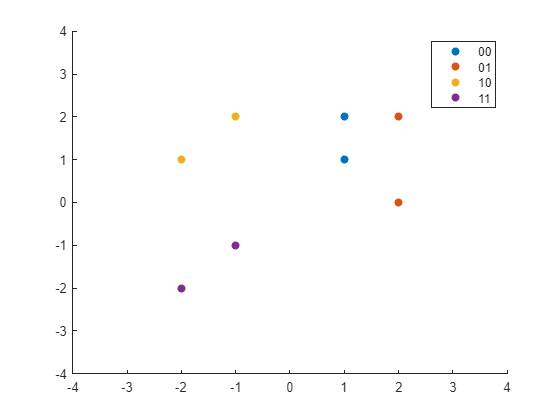

class_00 = [[1; 1; 0; 0], [1; 2; 0; 0]]; % p1, p2
class_01 = [[2; 2; 0; 1], [2; 0; 0; 1]]; % p3, p4
class_10 = [[-1; 2; 1; 0], [-2; 1; 1; 0]]; % p5, p6
class_11 = [[-1; -1; 1; 1], [-2; -2; 1; 1]]; % p7, p8
% Scatter plot of these data points
scatter(class_00(1,:), class_00(2,:), "filled", "DisplayName", "00");
hold on
scatter(class_01(1,:), class_01(2,:), "filled", "DisplayName", "01");
hold on
scatter(class_10(1,:), class_10(2,:), "filled", "DisplayName", "10");
hold on
scatter(class_11(1,:), class_11(2,:), "filled", "DisplayName", "11");
axis([-4, 4, -4, 4]);
legend('Location', 'best')
hold off

As we can see, with this change (P3 into [2, 2]) the problem does not seem to be linearly separable anymore as no two lines can classify all 4 classes.

We can however still attempt to find a best possible linear classifier.

**Network Construction and Training (II)**

Initializing random weights and biases:

weights = randn([2 2]);
biases = randn([2 1]);
fprintf('Starting weights:');

Starting weights:

disp(weights);

   -1.4916   -1.0616
   -0.7423    2.3505



fprintf('Starting biases:');

Starting biases:

disp(biases);

   -0.6156
    0.7481



% using hardlim as activation

Using Perceptron Rule to train the network. Training ends when we either hit the 50th epoch or we reach perfect accuracy.

all_data_points = [class_00 class_01 class_10 class_11];
epoch = 0;
num_tests = 8;
accuracy = 0.0;
% Training loop
while accuracy ~= 1.0 && epoch < 50
    passes = 0;
    fprintf('Start of epoch %d \n', epoch);
    for point=all_data_points
        xy = [point(1); point(2)];
        a = hardlim(weights*xy + biases);
        t = [point(3); point(4)];
        e = t-a;
        if e == 0
            passes = passes + 1;
        end
        weights = weights + e*xy';
        biases = biases + e;
    end
    accuracy = passes / num_tests;
    fprintf('Accuracy at the end of epoch %d: %f', epoch, accuracy);
    epoch = epoch + 1;
end

Start of epoch 0 


Accuracy at the end of epoch 0: 0.250000

Start of epoch 1 


Accuracy at the end of epoch 1: 0.625000

Start of epoch 2 


Accuracy at the end of epoch 2: 0.625000

Start of epoch 3 


Accuracy at the end of epoch 3: 0.750000

Start of epoch 4 


Accuracy at the end of epoch 4: 0.625000

Start of epoch 5 


Accuracy at the end of epoch 5: 0.750000

Start of epoch 6 


Accuracy at the end of epoch 6: 0.625000

Start of epoch 7 


Accuracy at the end of epoch 7: 0.625000

Start of epoch 8 


Accuracy at the end of epoch 8: 0.750000

Start of epoch 9 


Accuracy at the end of epoch 9: 0.625000

Start of epoch 10 


Accuracy at the end of epoch 10: 0.750000

Start of epoch 11 


Accuracy at the end of epoch 11: 0.875000

Start of epoch 12 


Accuracy at the end of epoch 12: 0.750000

Start of epoch 13 


Accuracy at the end of epoch 13: 0.625000

Start of epoch 14 


Accuracy at the end of epoch 14: 0.750000

Start of epoch 15 


Accuracy at the end of epoch 15: 0.875000

Start of epoch 16 


Accuracy at the end of epoch 16: 0.750000

Start of epoch 17 


Accuracy at the end of epoch 17: 0.625000

Start of epoch 18 


Accuracy at the end of epoch 18: 0.750000

Start of epoch 19 


Accuracy at the end of epoch 19: 0.875000

Start of epoch 20 


Accuracy at the end of epoch 20: 0.750000

Start of epoch 21 


Accuracy at the end of epoch 21: 0.625000

Start of epoch 22 


Accuracy at the end of epoch 22: 0.750000

Start of epoch 23 


Accuracy at the end of epoch 23: 0.875000

Start of epoch 24 


Accuracy at the end of epoch 24: 0.750000

Start of epoch 25 


Accuracy at the end of epoch 25: 0.625000

Start of epoch 26 


Accuracy at the end of epoch 26: 0.750000

Start of epoch 27 


Accuracy at the end of epoch 27: 0.875000

Start of epoch 28 


Accuracy at the end of epoch 28: 0.750000

Start of epoch 29 


Accuracy at the end of epoch 29: 0.625000

Start of epoch 30 


Accuracy at the end of epoch 30: 0.750000

Start of epoch 31 


Accuracy at the end of epoch 31: 0.875000

Start of epoch 32 


Accuracy at the end of epoch 32: 0.750000

Start of epoch 33 


Accuracy at the end of epoch 33: 0.625000

Start of epoch 34 


Accuracy at the end of epoch 34: 0.750000

Start of epoch 35 


Accuracy at the end of epoch 35: 0.875000

Start of epoch 36 


Accuracy at the end of epoch 36: 0.750000

Start of epoch 37 


Accuracy at the end of epoch 37: 0.625000

Start of epoch 38 


Accuracy at the end of epoch 38: 0.750000

Start of epoch 39 


Accuracy at the end of epoch 39: 0.875000

Start of epoch 40 


Accuracy at the end of epoch 40: 0.750000

Start of epoch 41 


Accuracy at the end of epoch 41: 0.625000

Start of epoch 42 


Accuracy at the end of epoch 42: 0.750000

Start of epoch 43 


Accuracy at the end of epoch 43: 0.875000

Start of epoch 44 


Accuracy at the end of epoch 44: 0.750000

Start of epoch 45 


Accuracy at the end of epoch 45: 0.625000

Start of epoch 46 


Accuracy at the end of epoch 46: 0.750000

Start of epoch 47 


Accuracy at the end of epoch 47: 0.875000

Start of epoch 48 


Accuracy at the end of epoch 48: 0.750000

Start of epoch 49 


Accuracy at the end of epoch 49: 0.625000

fprintf('Weights after training:');

Weights after training:

disp(weights);

   -2.4916    0.9384
    2.2577   -3.6495



fprintf('Biases after training:');

Biases after training:

disp(biases);

    0.3844
    4.7481



As we can see, the network cannot converge on a solution after 50 epochs and the accuracy is fluctuating around 0.625 and 0.875.

**Plotting the Classifier (II)**

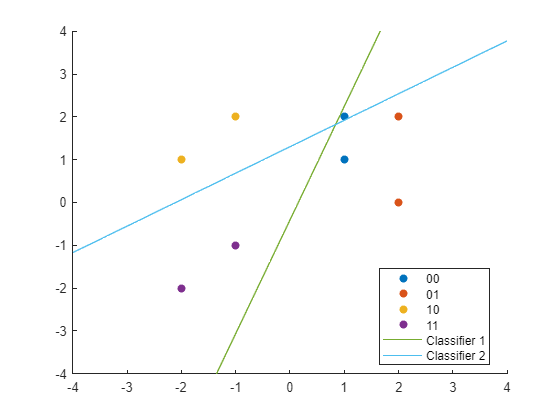

x = linspace(-4, 4);
y1 = (-weights(1, 1)*x - biases(1))/weights(1, 2);
y2 = (-weights(2, 1)*x - biases(2))/weights(2, 2);
scatter(class_00(1,:), class_00(2,:), "filled", "DisplayName", "00");
hold on
scatter(class_01(1,:), class_01(2,:), "filled", "DisplayName", "01");
hold on
scatter(class_10(1,:), class_10(2,:), "filled", "DisplayName", "10");
hold on
scatter(class_11(1,:), class_11(2,:), "filled", "DisplayName", "11");
plot(x, y1, "DisplayName", "Classifier 1");
hold on
plot(x, y2, "DisplayName", "Classifier 2");
axis([-4, 4, -4, 4]);
legend('Location','best')
hold off

**Changing P3 Again and Looking at the Data (III)**

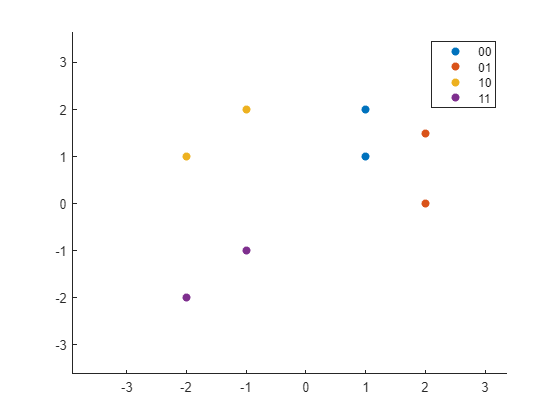

class_00 = [[1; 1; 0; 0], [1; 2; 0; 0]]; % p1, p2
class_01 = [[2; 1.5; 0; 1], [2; 0; 0; 1]]; % p3, p4
class_10 = [[-1; 2; 1; 0], [-2; 1; 1; 0]]; % p5, p6
class_11 = [[-1; -1; 1; 1], [-2; -2; 1; 1]]; % p7, p8
% Scatter plot of these data points
scatter(class_00(1,:), class_00(2,:), "filled", "DisplayName", "00");
hold on
scatter(class_01(1,:), class_01(2,:), "filled", "DisplayName", "01");
hold on
scatter(class_10(1,:), class_10(2,:), "filled", "DisplayName", "10");
hold on
scatter(class_11(1,:), class_11(2,:), "filled", "DisplayName", "11");
axis([-4, 4, -4, 4]);
legend('Location', 'best')
hold off

The problem now appears to be linearly classifiable and we can attempt to train a network that can correctly classify these patterns.

**Network Construction and Training and Plotting the Final Classifiers (IV)**

weights = randn([2 2]);
biases = randn([2 1]);
fprintf('Starting weights:');

Starting weights:

disp(weights);

   -0.1924   -0.7648
    0.8886   -1.4023



fprintf('Starting biases:');

Starting biases:

disp(biases);

   -1.4224
    0.4882



% using hardlim as activation
all_data_points = [class_00 class_01 class_10 class_11];
epoch = 0;
num_tests = 8;
accuracy = 0.0;
% Training loop
while accuracy ~= 1.0 && epoch < 50
    passes = 0;
    fprintf('Start of epoch %d \n', epoch);
    for point=all_data_points
        xy = [point(1); point(2)];
        a = hardlim(weights*xy + biases);
        t = [point(3); point(4)];
        e = t-a;
        if e == 0
            passes = passes + 1;
        end
        weights = weights + e*xy';
        biases = biases + e;
    end
    accuracy = passes / num_tests;
    fprintf('Accuracy at the end of epoch %d: %f', epoch, accuracy);
    epoch = epoch + 1;
end

Start of epoch 0 


Accuracy at the end of epoch 0: 0.750000

Start of epoch 1 


Accuracy at the end of epoch 1: 1.000000

fprintf('Weights after training:');

Weights after training:

disp(weights);

   -2.1924    0.2352
    0.8886   -1.4023



fprintf('Biases after training:');

Biases after training:

disp(biases);

    0.5776
    0.4882



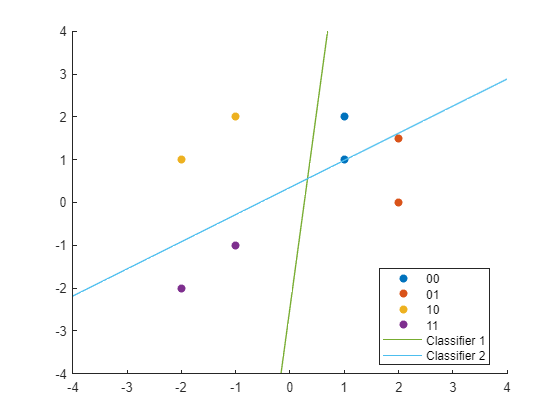

x = linspace(-4, 4);
y1 = (-weights(1, 1)*x - biases(1))/weights(1, 2);
y2 = (-weights(2, 1)*x - biases(2))/weights(2, 2);
scatter(class_00(1,:), class_00(2,:), "filled", "DisplayName", "00");
hold on
scatter(class_01(1,:), class_01(2,:), "filled", "DisplayName", "01");
hold on
scatter(class_10(1,:), class_10(2,:), "filled", "DisplayName", "10");
hold on
scatter(class_11(1,:), class_11(2,:), "filled", "DisplayName", "11");
plot(x, y1, "DisplayName", "Classifier 1");
hold on
plot(x, y2, "DisplayName", "Classifier 2");
axis([-4, 4, -4, 4]);
legend('Location','best')
hold off

As we can see, the issue with the previous choice for P3 was that [2, 2] would lie in the same line as [1, 1] from class 00 and [-1, -1] and [-2, -2] from class 11. Therefore no single line could isolate exactly two of these classes. With the new choice for P3 however, i.e., [2, 1.5] we can see that a line can barely pass through and isolate 01 and 11 from 00 and 10.